confirmed = loadData('confirmed');
deaths = loadData('deaths');
recovered = loadData('recovered');

region = 12; % Queensland
t = 12:width(confirmed);
qlpop = 5072000; 
s1 = qlpop - confirmed{region,t} - deaths{region,t} - recovered{region,t};
i1 = confirmed{region,t} - deaths{region,t} - recovered{region,t};
r1 = deaths{region,t} + recovered{region,t};

exp_y = [s1; i1; r1;]

exp_y =      5071999     5071997     5071998     5071997     5071998     5071998     5071997     5071997     5071996     5071995     5071995     5071995     5071995     5071995     5071995     5071995     5071995     5071995     5071995     5071995     5071995     5071995     5071995     5071994     5071994     5071994     5071994     5071994     5071994     5071994     5071994     5071990     5071990     5071990     5071988     5071988     5071979     5071979     5071979     5071977     5071977     5071974     5071972     5071972     5071957     5071946     5071931     5071924     5071914     5071898
           1           3           2           3           2           2           3           3           4           5           5           5           5           5           5           5           5           5           5           5           5           5           5           4           4           4           4           4           4           4           4           8       

exp_t = 1:length(i1);
p0 = [0.341 0.141]; %initial guess for beta and gamma, based on real world data
p_estimate = fminsearch(@(p)odefit(exp_t,exp_y,p),p0)

p_estimate =     8.0602    8.0542


[~,Y] = ode45(@(t,y)odefun(t,y,p_estimate),exp_t,[5072000 1 0]);

S = Y(:,1); 
I = Y(:,2) 

I =     1.0000
    1.0060
    1.0120
    1.0181
    1.0242
    1.0303
    1.0364
    1.0426
    1.0487
    1.0549


R = Y(:,3)

R = 	1.0e+03 *

         0
    0.0081
    0.0162
    0.0244
    0.0326
    0.0409
    0.0492
    0.0576
    0.0660
    0.0745


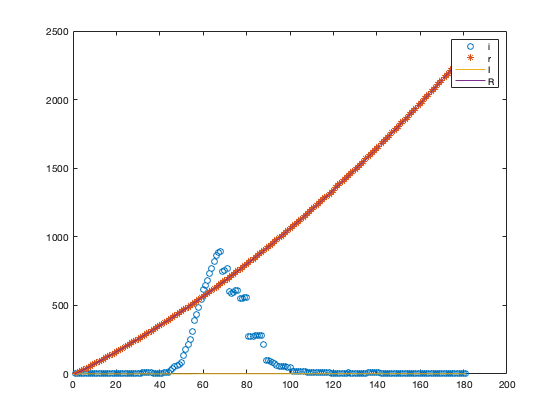

plot(exp_t,i1,'o',exp_t,R,'*',exp_t,I,exp_t,R)
legend('i','r','I','R')

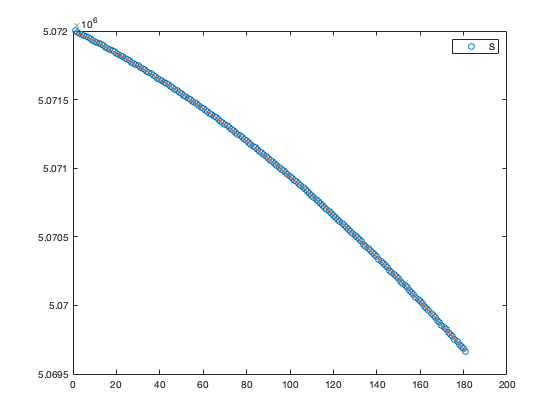

figure
plot(exp_t,S,'o',exp_t,S)
legend('S')